# MLIB toolbox - a library of Matlab integrated software for seismic processing

**Author**: Ivan Abakumov

**Publication date**: 23rd October 2017

**E-mail**: ivan.abakumov@fu-berlin.de

## Introduction

MATLAB has become a common tool in many research areas. MATLAB is a very user friendly programming language and suggests rich opportunities for development and research. For scientific computing, MATLAB includes a rich collection of built-in functions to solve a wide spectrum of mathematical problems. It's potential application can be further expanded by using optional toolboxes. As a result, a program written in MATLAB is relatively short and simple. Moreover, MATLAB offers powerful graphics capabilities, thus allowing easy to use visialization solutions to present the data.

Being an [interpreted language](https://en.wikipedia.org/wiki/Interpreted_language), MATLAB executes instructions directly, without previously compiling a program into machine-language instructions. Hence, MATLAB is supposedly slow at loops compared to compiled languages like C, C++ or Fortran. However, functions written in the C/C++ or Fortran programming language, can be linked to MATLAB by using MEX library. [MEX library](https://de.mathworks.com/help/matlab/ref/mex.html) allows to create MEX files from C/C++ or Fortran functions, that can be used and called directly from MATLAB as a built-in functions. Thus, a convenience of MATLAB can be combined with the high performance of C/C++ or Fortran languages. 

Reproducibility of research results is one of the key issues in the scientific community. MATLAB codes, together with supplementary content (comments, equations) and output can be published to the numerous formats, for example as PDF files. Such published documents can be used for sharing results with colleagues, teaching or demonstration as well as for generating comprehensible external documentation, thus making the research more reproducible. 

During the last years, MATLAB was my everyday tool for research, designing programs and testing ideas. I applied it for a variety of purposes, including:

- Time imaging

- Time lapse seismic

- Traveltime tomography

- Eikonal solvers, ray tracing

- Localization of microseismic events

- FD modelling, FWI

- Static corrections

- Virtual source method

- I/O of X-Well, OBN, Microseismic, 2D/3D marine and field datasets. 

I found it helpful to collect the commonly used functions in the library, called MLIB. I also gathered Matlab-related open-source codes, that could be useful for seismic problems. In this script, I will demonstrate some tools of the MLIB library and several rarely used, but extremely useful features of MATLAB. In particular, I will demonstrate how to: 

- add MLIB library

- read, write and analize SEGY/SU/SEG2 files

- use Eikonal solvers and ray tracing

- run 2D FD modeling

- perform quasi-Newton optimization method

I hope that MLIB library might be a usefull tool for fresh geophyscs students starting with MATLAB.

## How to add MLIB library?

You can upload the latest MLIB release from [GitHub](https://github.com/Abakumov/MLIB.git)[ ](http:// https://github.com/Abakumov/MLIB.git)

In MATLAB, add MLIB by the following command:

clear; clc;

mlibfolder = '/data/ivan/share/MLIB';
path(path, mlibfolder);
addmlibpath;

current_folder = pwd;

Variable **mlibfolder** defines the path to MLIB library on your computer. 

## Add Linux commands inside MATLAB code

All commands starting with the exclamation mark are interpreted by shell: 

cd /data/ivan/share/demo_su/

! segyread tape=data_example.sgy > data_example.su

3200+0 records in
6+1 records out
3200 bytes (3.2 kB) copied, 0.0022994 s, 1.4 MB/s



! surange < data_example.su

12810 traces:
tracl    1 12810 (1 - 12810)
tracr    1 12810 (1 - 12810)
fldr     1 141 (56 - 141)
tracf    1 130 (1 - 130)
cdp      807062 1192560 (807062 - 1192560)
trid     1
offset   -236 234 (146 - 15)
gelev    807 1193 (807 - 1193)
selev    791 1208 (953 - 1208)
sdepth   807062 1192560 (807062 - 1192560)
swdep    -234051 236220 (-146306 - -15210)
gwdep    880215 1200165 (880215 - 1200165)
scalel   1
scalco   1
sx       10 38 (26 - 38)
gx       263 285 (263 - 284)
counit   1
ns       522
dt       1000

Shot coordinate limits:
	North(26,0) South(26,0) East(38,0) West(10,0)

Receiver coordinate limits:
	North(263,0) South(263,0) East(285,0) West(263,0)

Midpoint coordinate limits:
	North(144.5,0) South(144.5,0) East(161.5,0) West(144.5,0)



! rm -f binary header 


cd(current_folder)


## SeisLab

Several years ago `Eike Rietsch` developed a special library for seismic needs - [SeisLab](https://de.mathworks.com/matlabcentral/fileexchange/53109-seislab-3-02). This library includes about 170 functions for analysis and display of exploration-seismic data and well logs. These functions read and write seismic data in standard SEG-Y format, read and write well logs in LAS-format 2.0. 

Since there is a pdf [manual](http://www.kfben.com/dfilea/28084390MatlabSeislab/S4M_3p014PD.pdf) about SeisLab, I refer to it for examples and scripts. 

## Read SU files

Very often it is necessary to check headers and aquisition geometry of field data. With MLIB it is possible to do in few lines: 

sufilename = '/data/ivan/share/demo_su/data_example.su';
data = read_su_file(sufilename);

/data/ivan/share/demo_su/data_example.su
/data/ivan/share/demo_su/data_example.sgy


header = get_segy_headers(data);
 

Plot all acquisition geometry

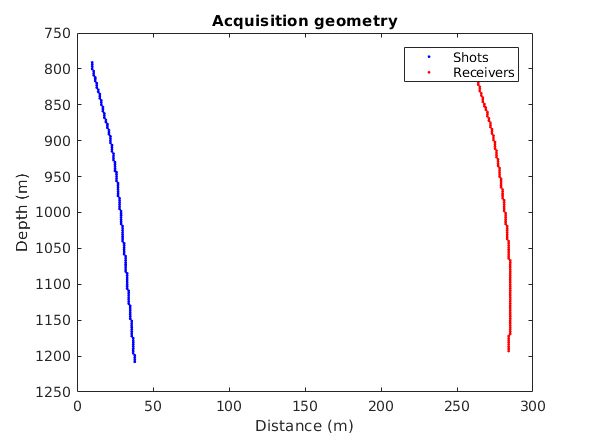

figure(1)
plot(header.sx, header.sz, '.b')
hold on 
plot(header.rx, header.rz, '.r')
axis([0 300 750 1250])
xlabel('Distance (m)');
ylabel('Depth (m)')
title('Acquisition geometry'); 
legend('Shots', 'Receivers');
set(gca, 'YDir', 'reverse')

## Eikonal solvers

MLIB contains Eikonal solvers based on the fast sweeping method. The FSM is a method for computing the numerical solution of Eikonal equations on a rectangular grid. Theory of method is explained in [1]. Currently 2D, 3D, 2D VTI and 2D version for curvilinear grids are available. 

- Initialize grid array 


G=GridClass;

% [m]        [m]          [m]          [s]
G.x0=0;     G.y0=0;     G.z0=0;        G.t0 = 0.00;          % initial point
G.nx=201;   G.ny=201;   G.nz=201;      G.nt = 500;           % grid size
G.dx=5;     G.dy=5;     G.dz=5;        G.dt = 0.001;         % grid step (meter)

G.gridInfo;

Information about grid:
x0=0, dx=5, Nx=201.
y0=0, dy=5, Ny=201.
z0=0, dz=5, Nz=201.
t0=0, dt=0.001, Nt=500.


G.setGrid;
Gold = oldGrid(G); 

- Create velocity model

v0 = 3200;  % m/s 
dv = 0.5;   % 1/s

velmod=ones(G.nx,G.ny,G.nz);
for i=1:G.nz
    velmod(:,:,i) = v0 + G.zz(i)*dv; 
end

- Define source position

S = [500,200,900];

- Plot velocity model

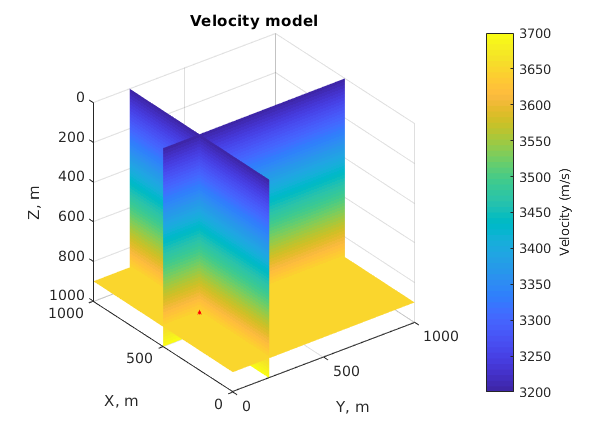

figure(2)
h=slice(G.yy,G.xx,G.zz,velmod,S(2),S(1),S(3));
set(h,'FaceColor','interp','EdgeColor','none','DiffuseStrength',.8)
hold on
plot3(S(2),S(1),S(3),'r*');
axis ([G.y0 G.my G.x0 G.mx G.z0 G.mz]);
set(gca,'Zdir','reverse'); 
axis image; c=colorbar;
c.Label.String='Velocity (m/s)';
xlabel('Y, m');ylabel('X, m');zlabel('Z, m');
title('Velocity model')

- Run 3D FSM code    

tic
tti = FSM3D(Gold,S,velmod);
toc

Elapsed time is 5.609021 seconds.


- Plot traveltimes

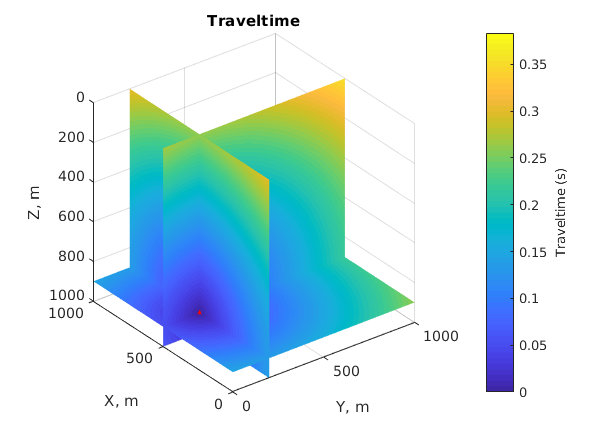

figure(2)
h=slice(G.yy,G.xx,G.zz,tti,S(2),S(1),S(3));
set(h,'FaceColor','interp','EdgeColor','none','DiffuseStrength',.8)
hold on
plot3(S(2),S(1),S(3),'r*');
axis ([G.y0 G.my G.x0 G.mx G.z0 G.mz]);
set(gca,'Zdir','reverse'); 
axis image; c=colorbar;
c.Label.String = 'Traveltime (s)';
xlabel('Y, m');ylabel('X, m');zlabel('Z, m');
title('Traveltime')

## FD modeling

MLIB library includes EL2D code for wavefield modeling in 2D elastic media. The EL2D code is based on the original standalone C code created by Ekkehart Tessmer. The code is designed for wavefield modeling in 2D elastic media with pseudospectral Fourier method [3]. Mex wrapper was designed by Denis Anikiev.

The code accepts two modes of modeling: 

- modeling with point source

- modeling with boundary condition as a source

G = MLD('/data/ivan/share/demo_fd/OBN_DIFF_G_file.mat');
Gold = oldGrid(G);
velmod = MLD('/data/ivan/share/demo_fd/OBN_DIFF_mvelmod.mat');
acq = MLD('/data/ivan/share/demo_fd/OBN_DIFF_acquisition.mat');

Plot velocity model and acquisition

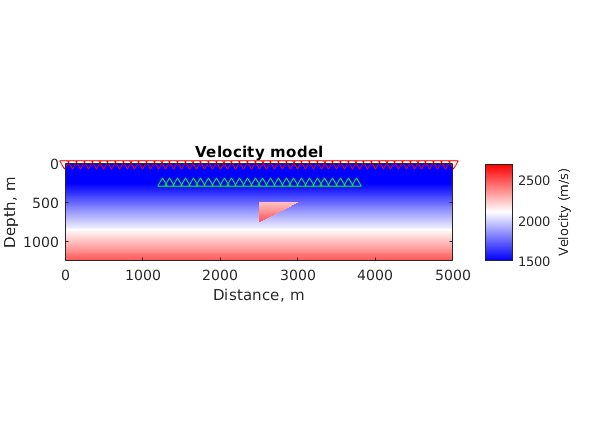

figure(4)
imagesc(G.xx, G.zz, velmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'rv')
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([0 5000 0 1250]); 
c = colorbar('Ticks', [1500,2000,2500]);
c.Label.String = 'Velocity (m/s)';
caxis([1500, 2700])
title('Velocity model')
xlabel('Distance, m')
ylabel('Depth, m')

colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));


Calculate wavefields

fpeak = 20; 
shotnum = [8 16 24]; 
 
[f10,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, velmod);

Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 3


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 3; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 206; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 72.770979 seconds.


Calculate traveltimes of diffraction events

tshift = 0.0825; % sec

S1 = [2500, 500];
S2 = [2500, 750];
S3 = [3000, 500];

tti1 = FSM2D(Gold,S1,velmod);
tti2 = FSM2D(Gold,S2,velmod);
tti3 = FSM2D(Gold,S3,velmod);

Make snapshots

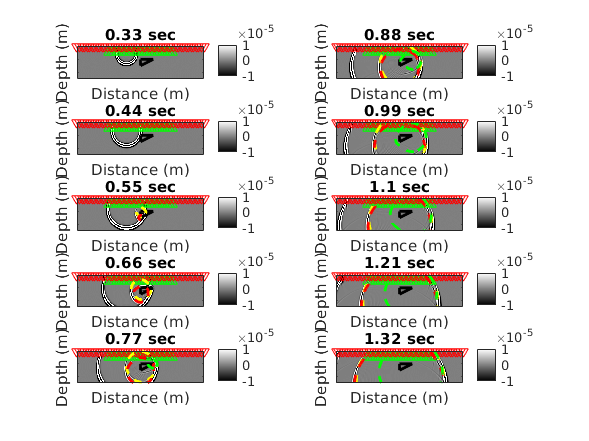

ind = [121 321 161 361 201 401 241 441 281 481];
figure(6)
for j=1:1:10
%for j=7:7
    subplot(5,2,j)
    imagesc(G.xx, G.zz, squeeze(f10(:,:,ind(j),1))')
    hold on
    plot(acq.sx, acq.sz, 'g^')
    plot(acq.rx(1:8:401), acq.rz(1:8:401), 'rv')
    plot(linspace(2500,3000,250), linspace(750,500,250), '-black', 'LineWidth',2); 
    plot(linspace(2500,3000,250), linspace(500,500,250), '-black', 'LineWidth',2);
    plot(linspace(2500,2500,250), linspace(500,750,250), '-black', 'LineWidth',2);
    axis('equal')
    set(gca,'XTickLabel',[]);
    set(gca,'YTickLabel',[]);
    set(gca, 'YDir', 'Reverse')
    [~,h] = contour(G.xx,fliplr(G.zz),flipud(tti1(acq.gsx(8),acq.gsz(8))+tti1'+tshift),[G.tt(ind(j)) G.tt(ind(j))], 'color','y','ShowText','off');
    h.LineWidth = 2;
    h.LineStyle = '--'; 
    [~,h] = contour(G.xx,fliplr(G.zz),flipud(tti2(acq.gsx(8),acq.gsz(8))+tti2'+tshift),[G.tt(ind(j)) G.tt(ind(j))], 'color','r','ShowText','off');
    h.LineWidth = 2;
    h.LineStyle = '--'; 
    [~,h] = contour(G.xx,fliplr(G.zz),flipud(tti3(acq.gsx(8),acq.gsz(8))+tti3'+tshift),[G.tt(ind(j)) G.tt(ind(j))], 'color','g','ShowText','off');
    h.LineWidth = 2;
    h.LineStyle = '--'; 
    xlabel('Distance (m)'); 
    ylabel('Depth (m)');
    axis([0 5000 0 1250]); 
    caxis([-0.00001, 0.00001])
    title([num2str(G.tt(ind(j))) ' sec'])
    colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
    colormap('gray')
    colorbar
end

## L-BFGS-B

[L-BFGS-B](https://en.wikipedia.org/wiki/Limited-memory_BFGS) is a limited-memory quasi-Newton code for bound-constrained optimization, i.e., for problems where the only constraints are of the form l<= x <= u. 

Authors of the [original fortran](http://users.iems.northwestern.edu/~nocedal/lbfgsb.html) code: Ciyou Zhu, Richard Byrd, Jorge Nocedal and Jose Luis Morales

[MEX wrapper](https://de.mathworks.com/matlabcentral/fileexchange/35104-lbfgsb--l-bfgs-b--mex-wrapper) was created by *Stephen Becker.*

L-BFGS-B is commonly used in full waveform inversion and tomorgaphy.  

**Example**: test the "lbfgs" on the Hock & Schittkowski test problem #38 (see [2]): 

Find minimum of function:


$$f = 100 (x_2-x_1^2)^2 + (1-x_1)^2 + 90 (x_4-x_3^2)^2 + (1-x_3)^2 +10.1 (x_2-1)^2 + 10.1 (x_4-1)^2 + 19.8 (x_2-1)(x_4-1);$$


The gradient of function is equal: 

 
$$\frac{\partial \text{ }f}{\partial \text{ }x_1 }=-400\text{ }x_1 \text{ }\left(x_2 -x_1^2 \right)-2\left(1-x_1 \right);$$



$$\frac{\partial \text{ }f\text{ }}{\partial \text{ }x_2 }=200\left(x_2 -x_1^2 \right)+20\ldotp 2\left(x_2 -1\right)+19\ldotp 8\left(x_4 -1\right);$$



$$\frac{\partial \text{ }f}{\partial \text{ }x_3 }=-360\text{ }x_3 \left(x_4 -x_3^2 \right)-2\left(1-x_3 \right);$$



$$\frac{\partial \text{ }f\text{ }}{\partial \text{ }x_4 }=-400\text{ }x_1 \left(x_2 -x_1^2 \right)-2\left(1-x_1 \right);$$


**Solution**: $f$ reaches minimum ($f=0$)  at point $x=[1,1,1,1]$.

x0  = [-3  -1  -3  -1];   % The starting point.
lb  = [-10 -10 -10 -10];  % Lower bound on the variables.
ub  = [+10 +10 +10 +10];  % Upper bound on the variables.

x = lbfgsb(x0,lb,ub,'computeObjective','computeGradient',...
               [],'genericcallback','maxiter',80,'m',4,'factr',1e-12,...
               'pgtol',1e-5);

  1  573 
  2  393 
  3  132 
  4  11.5 
  5  1.48 
  6  1.12 
  7  0.984 
  8  0.305 
  9  0.0847 
 10  0.0101 
 11  0.000123 
 12  0.000113 
 13  0.000113 
 14  0.000112 
 15  0.000109 
 16  9.75e-05 
 17  7.93e-05 
 18  7.17e-05 
 19  3.55e-05 
 20  1.46e-05 
 21  1.71e-06 
 22  1.94e-07 
 23  1.47e-07 
 24  8.84e-10 
 25  2e-11 
 26  2.21e-12 
 27  7.16e-14 


disp(x)

    1.0000    1.0000    1.0000    1.0000



## Literature

[1] Zhao, H. [2005] A fast sweeping method for solving Eikonal equations, Math Comput Vol. 74, pp. 603-627

[2] Hock, W. and Schittkowski, K. [1981] Test Examples for Nonlinear Programming Codes. Lecture Notes in Economics and Mathematical Systems Vol. 187, Springer-Verlag.

[3] Kosloff, D., and Reshef, M. and Loewenthal, D. [1984] Elastic wave calculations by the Fourier method, Bulletin of the Seismological Society of America, Vol. 74, pp. 875-891